syms u

u = t;

t_vals = linspace(0, 30, 100);

rainbow_road_center_line = [
            0.3960 * cos(2.65 * (u + 1.4)),
            -0.99 * sin(u + 1.4)
];

neato_max_speed = 0.3;
neato_min_speed = -0.3;
wheel_dist = 0.245;

u_range = [0, 3.2];
full_u_range = linspace(u_range(1), u_range(2), 100);
magnitude = @(vec) simplify(sqrt(sum(vec.^2)));

rainbow_road_center_line_vel = diff(rainbow_road_center_line);
rainbow_road_center_line_speed = magnitude(rainbow_road_center_line_vel)

$$rainbow\_road\_center\_line\_speed = \frac{99\,\sqrt{2500\,{\cos\left(t+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{20}+\frac{371}{100}\right)}^{2}}}{5000}$$

rainbow_road_center_line_length = int(rainbow_road_center_line_speed, u, [0, u]);
rainbow_road_center_line_tangent_vec = rainbow_road_center_line_vel ./ rainbow_road_center_line_speed;
rainbow_road_center_line_tangent_vec_deriv = diff(rainbow_road_center_line_tangent_vec);
rainbow_road_center_line_norm_vec = rainbow_road_center_line_tangent_vec_deriv ./ norm(rainbow_road_center_line_tangent_vec_deriv);

rainbow_road_center_line_x(u) = rainbow_road_center_line(1);
rainbow_road_center_line_y(u) = rainbow_road_center_line(2);
rainbow_road_center_line_pos_data_x = double(rainbow_road_center_line_x(full_u_range));
rainbow_road_center_line_pos_data_y = double(rainbow_road_center_line_y(full_u_range));
rainbow_road_center_line_tangent_vec_x(u) = rainbow_road_center_line_tangent_vec(1);
rainbow_road_center_line_tangent_vec_y(u) = rainbow_road_center_line_tangent_vec(2);
rainbow_road_center_line_norm_vec_x(u) = rainbow_road_center_line_norm_vec(1);
rainbow_road_center_line_norm_vec_y(u) = rainbow_road_center_line_norm_vec(2);

rainbow_road_angular_velocity(u) = rainbow_road_center_line_tangent_vec_x * diff(rainbow_road_center_line_tangent_vec_y) - rainbow_road_center_line_tangent_vec_y * diff(rainbow_road_center_line_tangent_vec_x);

rainbow_road_vel_left = (rainbow_road_center_line_speed - (wheel_dist / 2) .* rainbow_road_angular_velocity);
rainbow_road_vel_right = (rainbow_road_center_line_speed + (wheel_dist / 2) .* rainbow_road_angular_velocity);




PLOTS (6.1, 6.2)

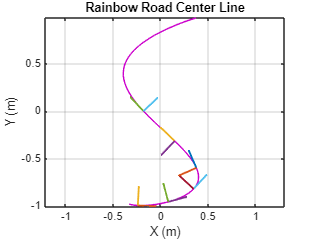

figure;
plot(rainbow_road_center_line_pos_data_x, rainbow_road_center_line_pos_data_y, Color=[0.8, 0, 0.8]); hold on
    for data_val = 5:10:60
        quiver( ...
            rainbow_road_center_line_pos_data_x(data_val), ...
            rainbow_road_center_line_pos_data_y(data_val), ...
            double(rainbow_road_center_line_tangent_vec_x(full_u_range(data_val))), ...
            double(rainbow_road_center_line_tangent_vec_y(full_u_range(data_val))), ...
            0.20, ...
            LineWidth=1.5 ...
        )
        quiver( ...
            rainbow_road_center_line_pos_data_x(data_val), ...
            rainbow_road_center_line_pos_data_y(data_val), ...
            double(rainbow_road_center_line_norm_vec_x(full_u_range(data_val))), ...
            double(rainbow_road_center_line_norm_vec_y(full_u_range(data_val))), ...
            0.20, ...
            LineWidth=1.5 ...
        )
    end
    title("Rainbow Road Center Line")
    xlabel("X (m)"); ylabel("Y (m)")
    grid on
    axis equal;
hold off

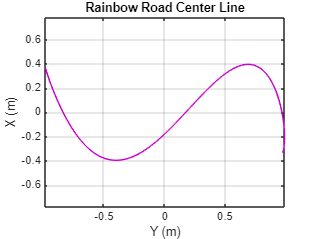


figure;
plot(rainbow_road_center_line_pos_data_y * -1, rainbow_road_center_line_pos_data_x, Color=[0.8, 0, 0.8]); hold on
    title("Rainbow Road Center Line")
    xlabel("Y (m)"); ylabel("X (m)")
    grid on
    axis equal;
hold off

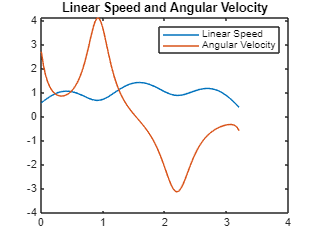


figure;
plot(full_u_range, double(subs(rainbow_road_center_line_speed, u, full_u_range))); hold on
    plot(full_u_range, double(subs(rainbow_road_angular_velocity, u, full_u_range)));
    legend("Linear Speed", "Angular Velocity")
    title("Linear Speed and Angular Velocity")
hold off

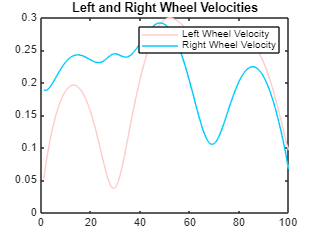


rainbow_road_vel_left_data = double(subs(rainbow_road_vel_left, u, full_u_range));
rainbow_road_vel_right_data = double(subs(rainbow_road_vel_right, u, full_u_range));
scaling_factor = max(rainbow_road_vel_left_data) / 0.3;

figure;
plot(rainbow_road_vel_left_data ./ scaling_factor, Color=[1, 0.8, 0.8]); hold on
    plot(rainbow_road_vel_right_data ./ scaling_factor, Color=[0, 0.8, 1]);
    title("Left and Right Wheel Velocities")
    legend("Left Wheel Velocity", "Right Wheel Velocity")
hold off